# Tutorial 2

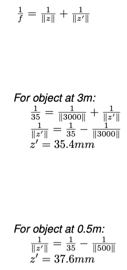

% If a lens has a focal length of 35mm at what depth should the image plane 
% be placed to bring an object 3m from the camera into focus? 
% What if the object is at 0.5m?

f = 35;
z = 3 * 1000; % m -> mm
find_depth(f,z)

ans = 35.4132


f = 35;
z = 0.5 * 1000;
find_depth(f,z)

ans = 37.6344

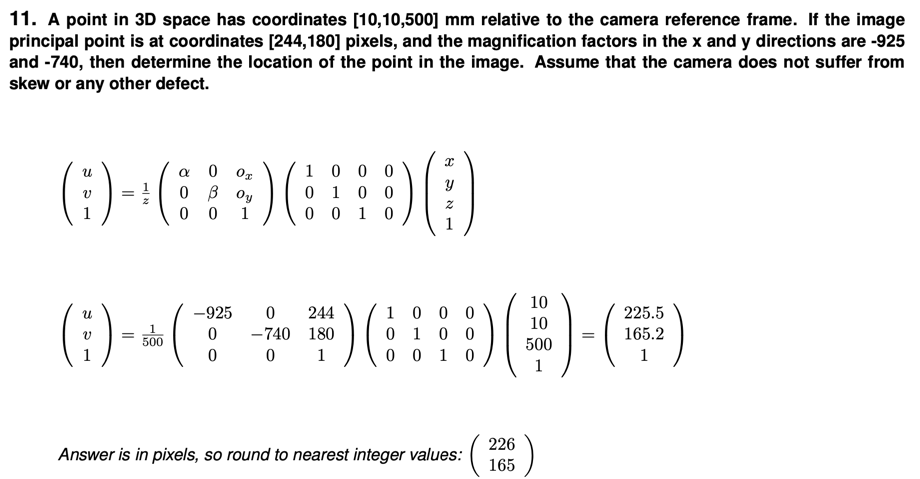

% A point in 3D space has coordinates [10,10,500] mm relative to the camera reference frame. If the image principal point is at coordinates [244,180] pixels, and the magnification factors in the x and y directions are -925 and -740, then determine the location of the point in the image. Assume that the camera does not suffer from skew or any other defect.
principal_point = [244 180]

principal_point =    244   180


x = -925

x = -925

y = -740

y = -740

point = [10 10 500]

point =     10    10   500



location_in_img(x,y,principal_point,point)

ans =   225.5000
  165.2000
    1.0000


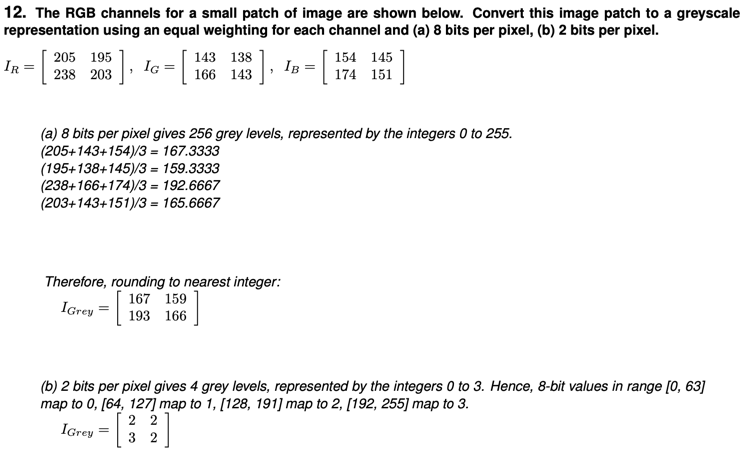

% The RGB channels for a small patch of image are shown below. Convert this image patch to a greyscale representation using an equal weighting for each channel and (a) 8 bits per pixel, (b) 2 bits per pixel.
IR = [205 195
      238 203];
IG = [143 138
      166 143];
IB = [154 145
      174 151];

img(:,:,1) = IR;
img(:,:,2) = IG;
img(:,:,3) = IB;

% 8bit
I_gray_8 = mean(img,3)

I_gray_8 =   167.3333  159.3333
  192.6667  165.6667



% 2bit
I_gray_2 = zeros(2);
for i = 1:4
    if I_gray_8(i) <= 63
        I_gray_2(i) = 0;
    
    elseif I_gray_8(i) <= 127
        I_gray_2(i) = 1;
    elseif I_gray_8(i) <= 191
        I_gray_2(i) = 2;
    else
        I_gray_2(i) = 3;
    end
end

I_gray_2

I_gray_2 =      2     2
     3     2


# Tutorial 3

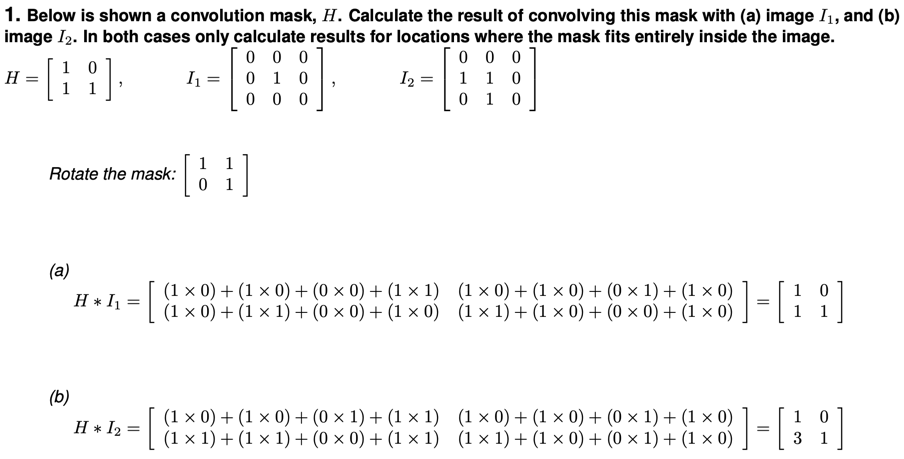

% Below is shown a convolution mask, H. Calculate the result of convolving this mask with (a) image I1, and (b) image I2. In both cases only calculate results for locations where the mask fits entirely inside the image.
H = [1 0
     1 1];

I1 = [0 0 0
      0 1 0
      0 0 0];

I2 = [0 0 0
      1 1 0
      0 1 0];

a = conv2(I1, H, "valid")

a =      1     0
     1     1


b = conv2(I2, H, "valid")

b =      1     0
     3     1


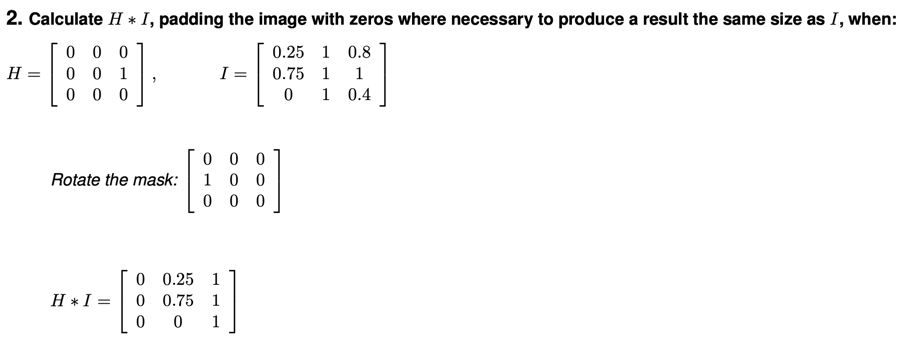

% Calculate H ∗ I, padding the image with zeros where necessary to produce a result the same size as I, when:
H = [0 0 0
     0 0 1
     0 0 0];

I = [0.25 1 0.8
     0.75 1 1
     0 1 0.4];

conv2(I, H, "same")

ans =          0    0.2500    1.0000
         0    0.7500    1.0000
         0         0    1.0000


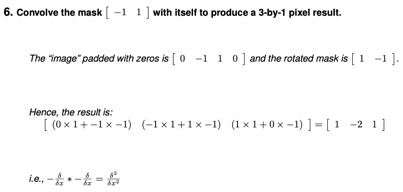

% Convolve the mask [−1 1] with itself to produce a 3-by-1 pixel result.
mask = [-1 1]

mask =     -1     1


conv2(mask, mask,"full")

ans =      1    -2     1


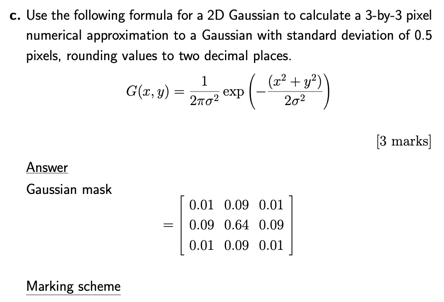

% 2016-2017, p11
% Use the following formula for a 2D Gaussian to calculate a 3-by-3 pixel numerical approximation to a Gaussian with standard deviation of 0.50 pixels, rounding values to two decimal places.
std = 0.5;

mask = zeros(3); % only for 3 by 3
for y = -1:1
    for x = -1:1
        mask(y+2, x+2) = gaussian2D(x,y,std);
    end
end

mask = round(mask, 2)

mask =     0.0100    0.0900    0.0100
    0.0900    0.6400    0.0900
    0.0100    0.0900    0.0100


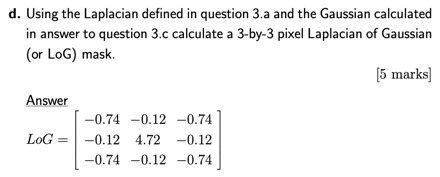

% 2016-2017, p11
% Using the Laplacian defined in question 3.a and the Gaussian calculated in answer to question 3.c calculate a 3-by-3 pixel Laplacian of Gaussian (or LoG) mask.
L = [-1 -1 -1
     -1 8 -1
     -1 -1 -1];

% it's a continuous question of the previous question -> has to get gaussian2D
conv2(L, mask, "same")

ans =    -0.7400   -0.1200   -0.7400
   -0.1200    4.7200   -0.1200
   -0.7400   -0.1200   -0.7400


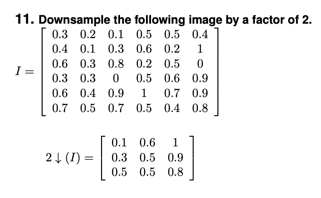

% Downsample the following image by a factor of 2.
I = [0.3 0.2 0.1 0.5 0.5 0.4
     0.4 0.1 0.3 0.6 0.2 1
     0.6 0.3 0.8 0.2 0.5 0
     0.3 0.3 0 0.5 0.6 0.9
     0.6 0.4 0.9 1 0.7 0.9
     0.7 0.5 0.7 0.5 0.4 0.8];

factor = 2;

I(factor:factor:end, factor:factor:end)

ans =     0.1000    0.6000    1.0000
    0.3000    0.5000    0.9000
    0.5000    0.5000    0.8000


# Tutorial 5

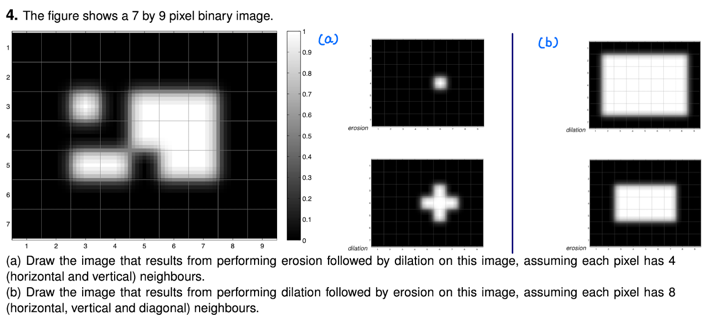

% (a) Draw the image that results from performing erosion followed by dilation on this image, assuming each pixel has 4 (horizontal and vertical) neighbours.
% (b) Draw the image that results from performing dilation followed by erosion on this image, assuming each pixel has 8 (horizontal, vertical and diagonal) neighbours.
im = [zeros(2,9)
    0 0 1 0 1 1 1 0 0
    0 0 0 0 1 1 1 0 0
    0 0 1 1 0 1 1 0 0
    zeros(2,9)];

% 4 neighbours
SE_4 = strel("diamond", 1);
erosion_4 = imerode(im, SE_4)

erosion_4 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


dailation_4 = imdilate(erosion_4, SE_4)

dailation_4 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0



% 8 neighbours
SE_8 = strel("square",3);
dailation_8 = imdilate(im, SE_8)

dailation_8 =      0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     0     0     0


erosion_8 = imerode(dailation_8, SE_8)

erosion_8 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     1     1     1     1     1     0     0
     0     0     1     1     1     1     1     0     0
     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


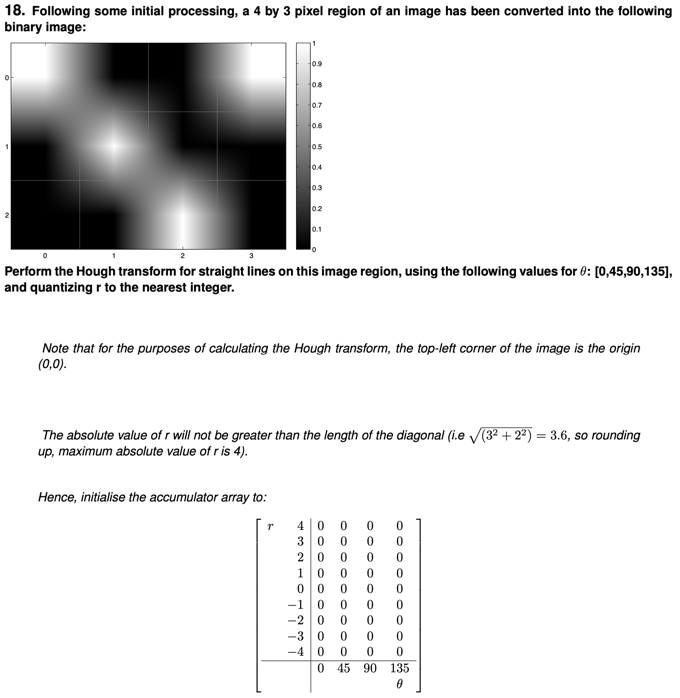

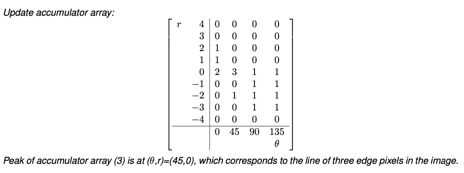

% Perform the Hough transform for straight lines on this image region, using the following values for θ: [0,45,90,135], and quantizing r to the nearest integer.
pixel_1 = [0 0];
pixel_2 = [1 1];
pixel_3 = [2 2];
pixel_4 = [3 0];

thetas = [0 45 90 135]

thetas =      0    45    90   135



% Count how many different numbers that each column has 
cal_lines(pixel_1, thetas)

ans =      0     0     0     0



cal_lines(pixel_2, thetas)

ans =      1     0    -1    -1



cal_lines(pixel_3, thetas)

ans =      2     0    -2    -3



cal_lines(pixel_4, thetas)

ans =      0    -2    -3    -2



% Peak of accumulator array (3) is at (θ,r)=(45,0), 
% which corresponds to the line of three edge pixels in the image.

# Tutorial 6

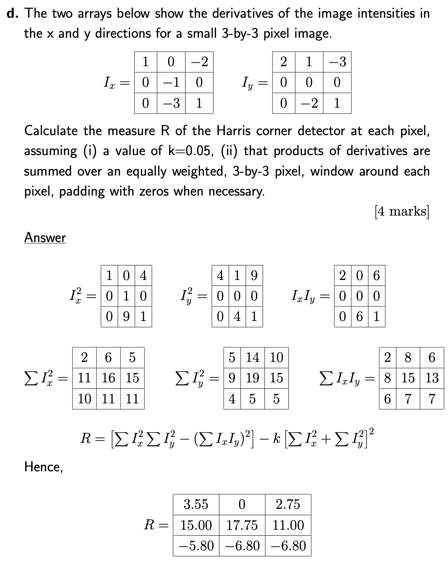

% 2016-17, p23
% Given the x any y derivatives of the image intensities shown above, calculate the response of the Harris corner detector at each of the six central pixels, assuming (a) a value of k=0.05, (b) that products of derivatives are summed over an equally weighted, 3 by 3 pixel, window around each pixel.

k = 0.05;

% Ix and Iy can be any size
Ix = [1 0 -2
      0 -1 0
      0 -3 1];

Iy = [2 1 -3
      0 0 0
      0 -2 1];

Ix_Iy = Ix .* Iy;

Ix_2 = Ix .^2;
Iy_2 = Iy .^2;

mask = [1 1 1
        1 1 1
        1 1 1];

sum_Ix_2 = conv2(Ix_2, mask, "same");
sum_Iy_2 = conv2(Iy_2, mask, "same");
sum_Ix_Iy = conv2(Ix_Iy, mask, "same");

R = (sum_Ix_2 .* sum_Iy_2 - sum_Ix_Iy .^2) - k * (sum_Ix_2 + sum_Iy_2) .^2

R =     3.5500         0    2.7500
   15.0000   17.7500   11.0000
   -5.8000   -6.8000   -6.8000


# Tutorial 8

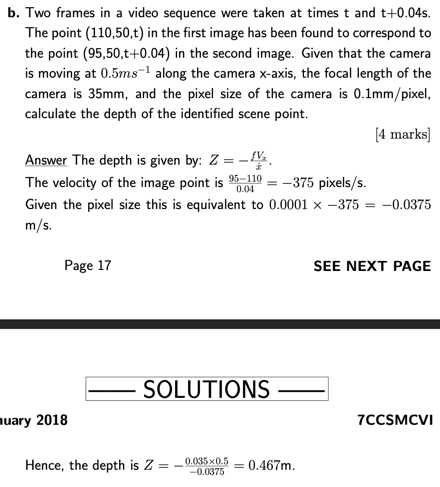

% 2017-2018, p17
% Two frames in a video sequence were taken at times t and t+0.04s. The point (110,50,t) in the first image has been found to correspond to the point (95,50,t+0.04) in the second image. Given that the camera is moving at 0.5ms−1 along the camera x-axis, the focal length of the camera is 35mm, and the pixel size of the camera is 0.1mm/pixel, calculate the depth of the identified scene point.
first_point = [110, 50];
second_point = [95, 50];
focal_length = 0.035;
time = 0.04;
cam_velocity = 0.5;
pixel_size = 0.1 * 100^-1;

img_velocity = (second_point(1) - first_point(1)) / time;
equivalent_pixel_size = pixel_size * img_velocity;

- (focal_length * cam_velocity) / equivalent_pixel_size

ans = 0.0467

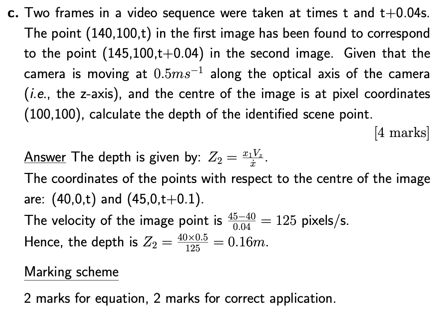

% 2017-2018, p18
% Two frames in a video sequence were taken at times t and t+0.04s. The point (140,100,t) in the first image has been found to correspond to the point (145,100,t+0.04) in the second image. Given that the camera is moving at 0.5ms−1 along the optical axis of the camera (i.e., the z-axis), and the centre of the image is at pixel coordinates (100,100), calculate the depth of the identified scene point.
first_point = [140, 100]

first_point =    140   100


second_point = [145, 100]

second_point =    145   100


center_point = [100, 100]

center_point =    100   100


time = 0.04

time = 0.0400

cam_velocity = 0.5

cam_velocity = 0.5000


% use x-coordinates
point_t = first_point - center_point;
point_t_1 = second_point - center_point;
img_velocity = (point_t_1(1) - point_t(1)) / time;
Z = (point_t(1) * cam_velocity) / img_velocity

Z = 0.1600

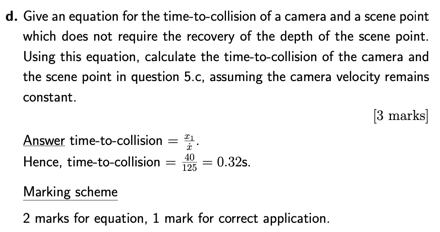

% 2017-2018, p18
% Give an equation for the time-to-collision of a camera and a scene point which does not require the recovery of the depth of the scene point. Using this equation, calculate the time-to-collision of the camera and the scene point in question 5.c, assuming the camera velocity remains constant.
time_to_collision = point_t(1) / img_velocity

time_to_collision = 0.3200

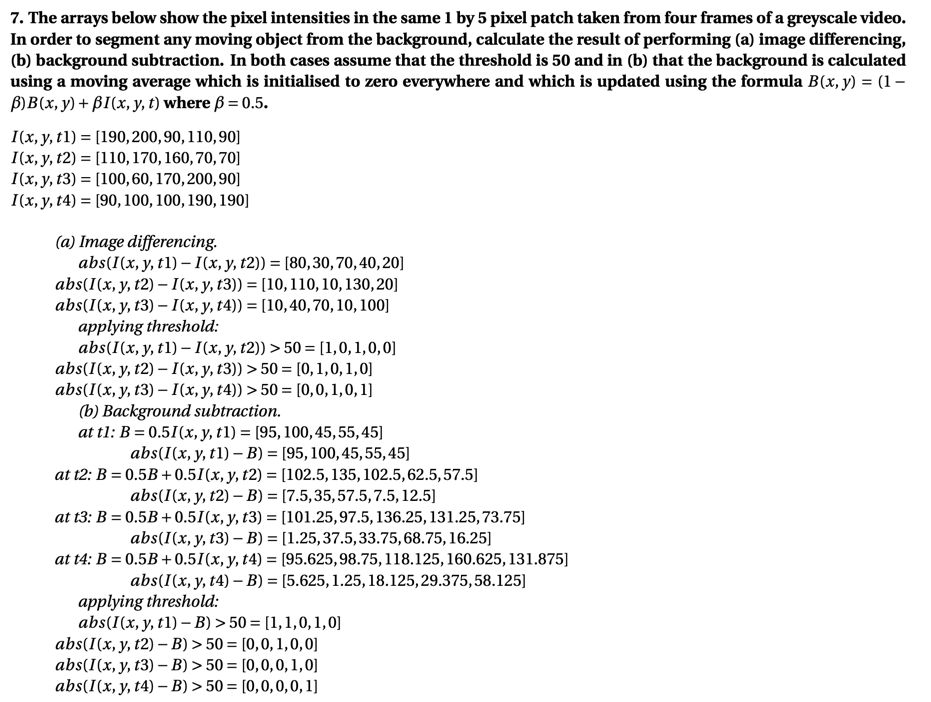

% The arrays below show the pixel intensities in the same 1 by 5 pixel patch taken from four frames of a greyscale video. In order to segment any moving object from the background, calculate the result of performing (a) image differencing, (b) background subtraction. In both cases assume that the threshold is 50 and in (b) that the background is calculated using a moving average which is initialised to zero everywhere and which is updated using the formula B(x,y) = (1− β)B(x,y)+βI(x,y,t) where β = 0.5.
I_t1 = [190 200 90 110 90];
I_t2 = [110 170 160 70 70];
I_t3 = [100 60 170 200 90];
I_t4 = [90 100 100 190 190];
th = 50;
beta = 0.5;

% Image differencing
abs(I_t1 - I_t2)

ans =     80    30    70    40    20


abs(I_t2 - I_t3)

ans =     10   110    10   130    20


abs(I_t3 - I_t4)

ans =     10    40    70    10   100


% applying threshold
abs(I_t1 - I_t2) > th

ans = 1×5 logical array
   1   0   1   0   0


abs(I_t2 - I_t3) > th

ans = 1×5 logical array
   0   1   0   1   0


abs(I_t3 - I_t4) > th

ans = 1×5 logical array
   0   0   1   0   1



% Background subtraction
t1_B = background_subtraction(I_t1, 0, beta);
abs(I_t1 - t1_B)

ans =     95   100    45    55    45



t2_B = background_subtraction(I_t2, t1_B, beta);
abs(I_t2 - t2_B)

ans =     7.5000   35.0000   57.5000    7.5000   12.5000



t3_B = background_subtraction(I_t3, t2_B, beta);
abs(I_t3 - t3_B)

ans =     1.2500   37.5000   33.7500   68.7500   16.2500



t4_B = background_subtraction(I_t4, t3_B, beta);
abs(I_t4 - t4_B)

ans =     5.6250    1.2500   18.1250   29.3750   58.1250



abs(I_t1 - t1_B) > th

ans = 1×5 logical array
   1   1   0   1   0


abs(I_t2 - t2_B) > th

ans = 1×5 logical array
   0   0   1   0   0


abs(I_t3 - t3_B) > th

ans = 1×5 logical array
   0   0   0   1   0


abs(I_t4 - t4_B) > th

ans = 1×5 logical array
   0   0   0   0   1


# Tutorial 9

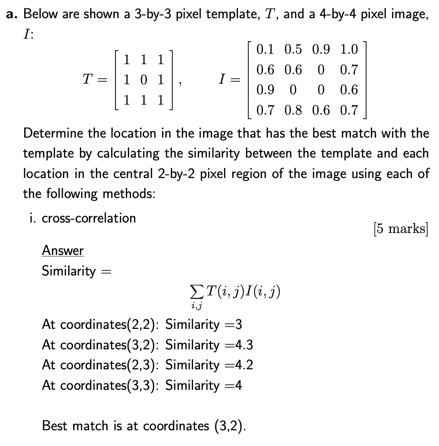

% 2019-2020, p30
% Determine the location in the image that has the best match with the
% template by calculating the similarity between the template and each location in the central 2-by-2 pixel region of the image using each of the following methods: cross-correlation
T = [1 1 1
     1 0 1
     1 1 1];

% It's a cross-correlation, not a convolution, rotate it bafore the conv2
% rotate it -> not be rotated
T_180 = rot90(T, 90);

I = [0.1 0.5 0.9 1.0
     0.6 0.6 0 0.7
     0.9 0 0 0.6
     0.7 0.8 0.6 0.7];

% check the middle 2 by 2 matrix position
conv2(I, T_180, "valid") % maximum

ans =     3.0000    4.3000
    4.2000    4.0000


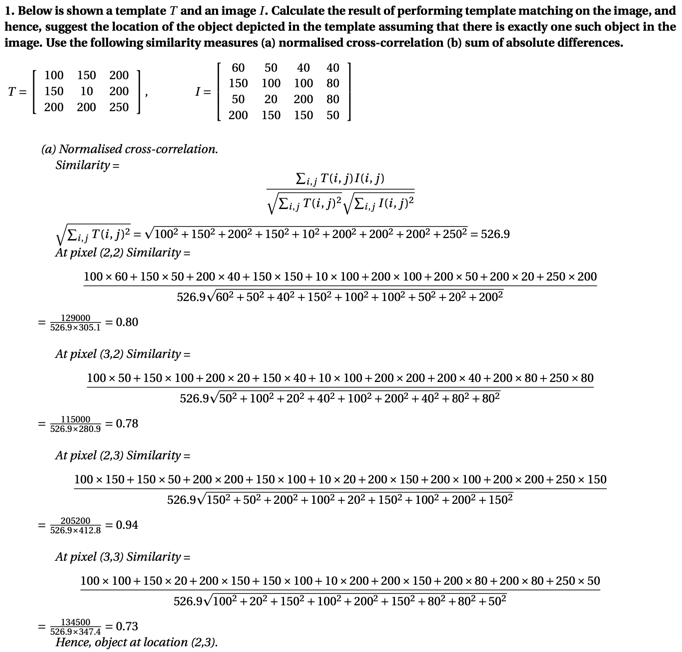

% Normalized cross-correlation
T = [100 150 200
     150 10 200
     200 200 250];

T_180 = rot90(T, 90);

I = [60 50 40 40
     150 100 100 80
     50 20 200 80
     200 150 150 50];

sqrt_sum_T_2 = sqrt(sum_matrix(T.^2));
I_2 = I.^2;

numerators = conv2(I, T_180, "valid");
denominators = zeros(2,2);
for i = 1:2
    for j = 1:2
        denominators(i,j) = sqrt_sum_T_2 * sqrt(sum_matrix(I_2(i:i+2,j:j+2)));
    end
end

% check the middle 2 by 2 matrix position
numerators ./ denominators % maximum

ans =     0.8024    0.7771
    0.9435    0.7348


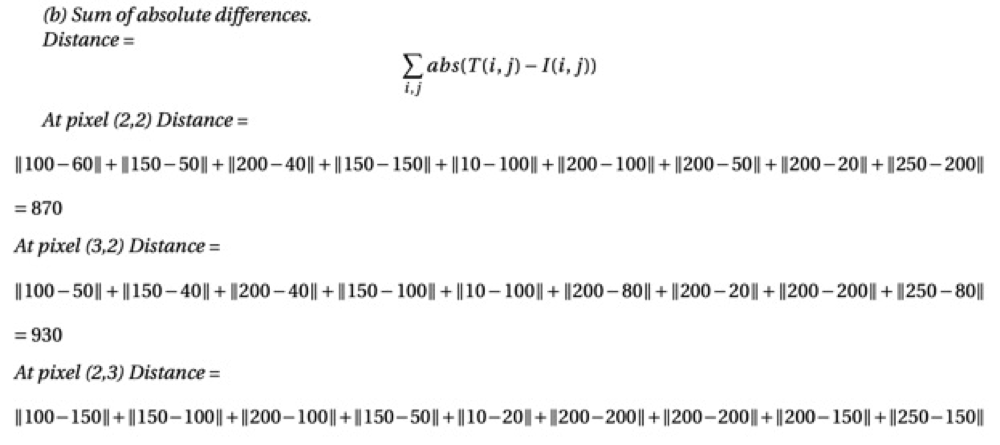

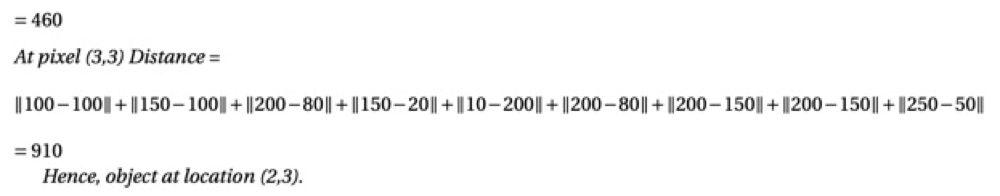

% Sum of absolute difference
pixels = zeros(2,2);
for i = 1:2
    for j = 1:2
        pixels(i,j) = sum_matrix(abs(T - I(i:i+2,j:j+2)));
    end
end

pixels % minimum

pixels =    870   930
   460   910


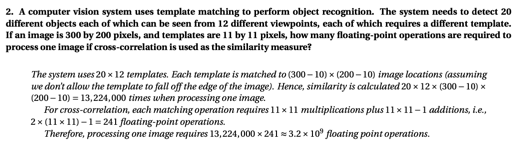

% A computer vision system uses template matching to perform object recognition. The system needs to detect 20 different objects each of which can be seen from 12 different viewpoints, each of which requires a different template. If an image is 300 by 200 pixels, and templates are 11 by 11 pixels, how many floating-point operations are required to process one image if cross-correlation is used as the similarity measure?
different_objects = 20;
different_viewpoints = 12;
image = [300 200];
template = [11 11];
similarity_calculation_times = different_objects * different_viewpoints * (image(1) - template(1) + 1) * (image(2) - template(2) + 1)

similarity_calculation_times = 13224000

matching_operation = 2 * template(1) * template(2) - 1

matching_operation = 241

floating_point_operation = similarity_calculation_times * matching_operation

floating_point_operation = 3.1870e+09

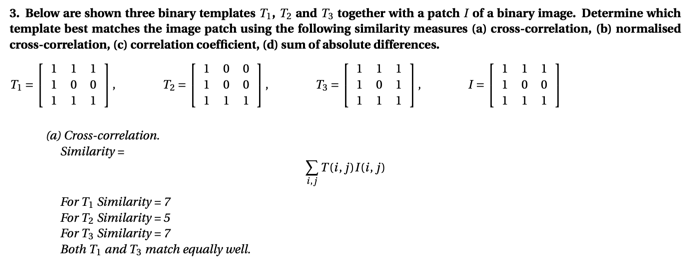

% Below are shown three binary templates T1, T2 and T3 together with a patch I of a binary image. Determine which template best matches the image patch using the following similarity measures (a) cross-correlation, (b) normalised cross-correlation, (c) correlation coefficient, (d) sum of absolute differences.
T1 = [1 1 1
      1 0 0
      1 1 1];

T2 = [1 0 0
      1 0 0
      1 1 1];

T3 = [1 1 1
      1 0 1
      1 1 1];

I = [1 1 1
     1 0 0
     1 1 1];

% (a) cross-correlation -> Maximum
T1_180 = rot90(T1, 90);
T1_numerator = conv2(I,T1_180,"valid")

T1_numerator = 7


T2_180 = rot90(T2, 90);
T2_numerator = conv2(I,T2_180,"valid")

T2_numerator = 5


T3_180 = rot90(T3, 90);
T3_numerator = conv2(I,T3_180,"valid")

T3_numerator = 7

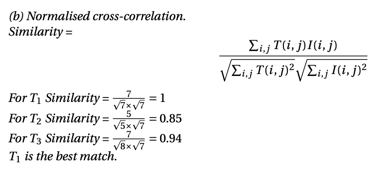

sqrt_sum_T1_2 = sqrt(sum(sum(T1.^2)));
sqrt_sum_T2_2 = sqrt(sum(sum(T2.^2)));
sqrt_sum_T3_2 = sqrt(sum(sum(T3.^2)));
I_2 = I.^2;

% (b) normalised cross-correlation -> Maximum
T1_numerator / (sqrt_sum_T1_2 * sqrt(sum_matrix(I_2)))

ans = 1.0000

T2_numerator / (sqrt_sum_T2_2 * sqrt(sum_matrix(I_2)))

ans = 0.8452

T3_numerator / (sqrt_sum_T3_2 * sqrt(sum_matrix(I_2)))

ans = 0.9354

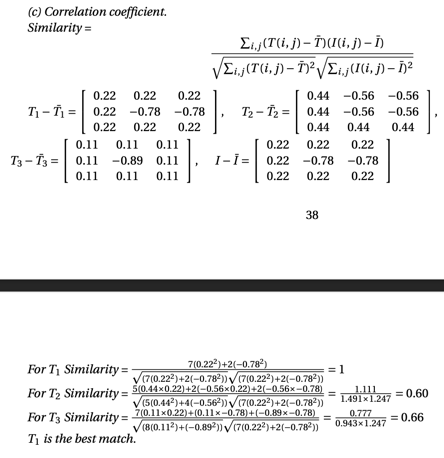

% (c) correlation coefficient -> Maximum
corr2(T1, I)

ans = 1

corr2(T2, I)

ans = 0.5976

corr2(T3, I)

ans = 0.6614

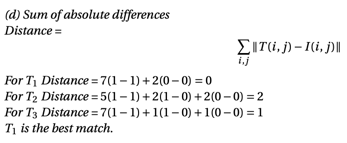

% (d) sum of absolute differences -> Minimum
sum_matrix(abs(T1-I))

ans = 0

sum_matrix(abs(T2-I))

ans = 2

sum_matrix(abs(T3-I))

ans = 1

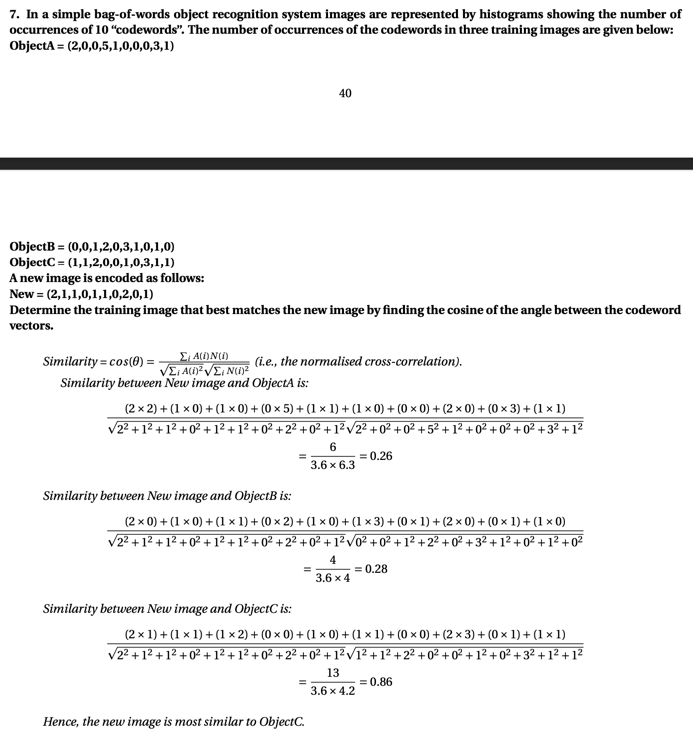

% In a simple bag-of-words object recognition system images are represented by histograms showing the number of occurrences of 10 “codewords”. The number of occurrences of the codewords in three training images are given below: ObjectA = (2,0,0,5,1,0,0,0,3,1)
O_A = [2 0 0 5 1 0 0 0 3 1];
O_B = [0 0 1 2 0 3 1 0 1 0];
O_C = [1 1 2 0 0 1 0 3 1 1];
new = [2 1 1 0 1 1 0 2 0 1];

% Miximum
sum(O_A .* new) / (sqrt(sum(O_A.^2)) * sqrt(sum(new.^2)))

ans = 0.2631

sum(O_B .* new) / (sqrt(sum(O_B.^2)) * sqrt(sum(new.^2)))

ans = 0.2774

sum(O_C .* new) / (sqrt(sum(O_C.^2)) * sqrt(sum(new.^2)))

ans = 0.8498

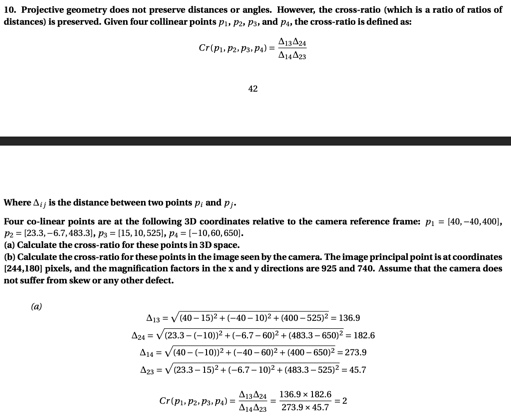

% Projective geometry does not preserve distances or angles. However, the cross-ratio (which is a ratio of ratios of distances) is preserved. Given four collinear points p1, p2, p3, and p4, the cross-ratio is defined as: Where∆ij isthedistancebetweentwopointspi andpj. Four co-linear points are at the following 3D coordinates relative to the camera reference frame: p1 = [40,−40,400], p2 = [23.3,−6.7,483.3], p3 = [15,10,525], p4 = [−10,60,650]. (a) Calculate the cross-ratio for these points in 3D space. (b) Calculate the cross-ratio for these points in the image seen by the camera. The image principal point is at coordinates [244,180] pixels, and the magnification factors in the x and y directions are 925 and 740. Assume that the camera does not suffer from skew or any other defect.
p1 = [40 -40 400];
p2 = [23.3 -6.7 483.3];
p3 = [15 10 525];
p4 = [-10 60 650];

delta_13 = sqrt(sum((p1-p3).^2))

delta_13 = 136.9306

delta_24 = sqrt(sum((p2-p4).^2))

delta_24 = 182.6107

delta_14 = sqrt(sum((p1-p4).^2))

delta_14 = 273.8613

delta_23 = sqrt(sum((p2-p3).^2))

delta_23 = 45.6801


(delta_13 * delta_24) / (delta_14 * delta_23)

ans = 1.9988

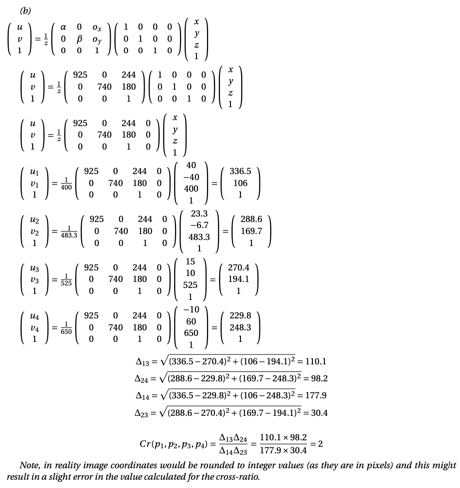

principal_point = [244 180];
x = 925;
y = 740;

p1_img = location_in_img(x,y,principal_point,p1);
p2_img = location_in_img(x,y,principal_point,p2);
p3_img = location_in_img(x,y,principal_point,p3);
p4_img = location_in_img(x,y,principal_point,p4);

delta_13 = sqrt(sum((p1_img(1:2) - p3_img(1:2)).^2))

delta_13 = 110.1190

delta_24 = sqrt(sum((p2_img(1:2) - p4_img(1:2)).^2))

delta_24 = 98.1482

delta_14 = sqrt(sum((p1_img(1:2) - p4_img(1:2)).^2))

delta_14 = 177.8846

delta_23 = sqrt(sum((p2_img(1:2) - p3_img(1:2)).^2))

delta_23 = 30.3827


(delta_13 * delta_24) / (delta_14 * delta_23)

ans = 1.9998

# Tutorial 10

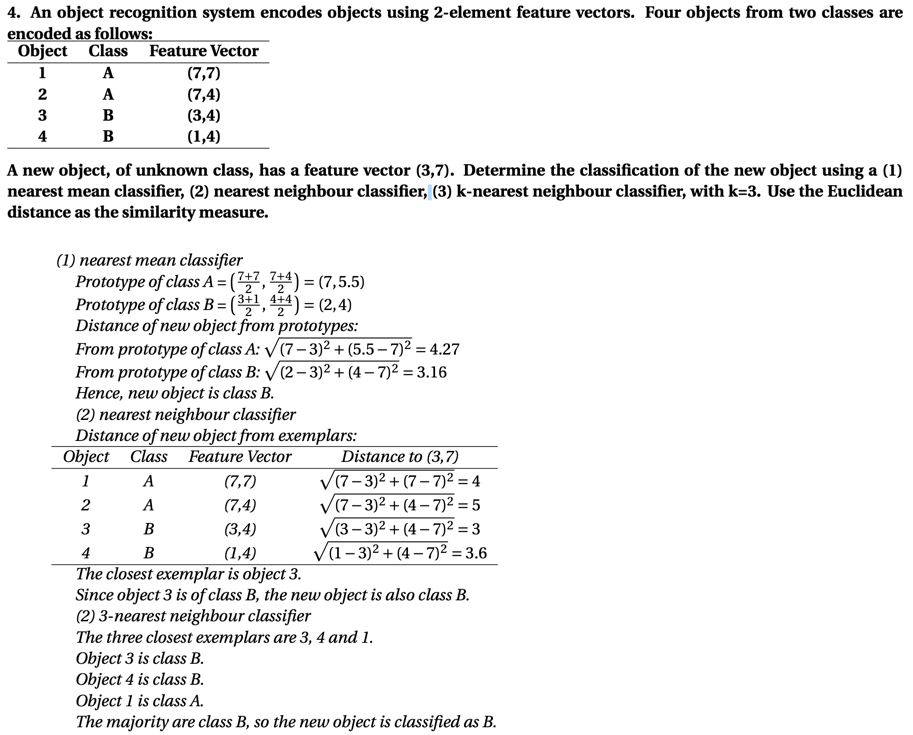

% An object recognition system encodes objects using 2-element feature vectors. Four objects from two classes are encoded as follows: A new object, of unknown class, has a feature vector (3,7). Determine the classification of the new object using a (1) nearest mean classifier, (2) nearest neighbour classifier, (3) k-nearest neighbour classifier, with k=3. Use the Euclidean distance as the similarity measure.
O1_A = [7 7];
O2_A = [7 4];
O3_B = [3 4];
O4_B = [1 4];
new_obj = [3 7];

% (1) Nearest mean classifier
prototype_A = (O1_A + O2_A) / 2;
prototype_B = (O3_B + O4_B) / 2;
% minimum
distance_from_A_to_new_obj = pdist2(prototype_A, new_obj, "euclidean")

distance_from_A_to_new_obj = 4.2720

distance_from_B_to_new_obj = pdist2(prototype_B, new_obj, "euclidean")

distance_from_B_to_new_obj = 3.1623


% (2) Nearest neighbour classifier
% Minimum
distance_from_O1_to_new_obj = pdist2(O1_A, new_obj, "euclidean")

distance_from_O1_to_new_obj = 4

distance_from_O2_to_new_obj = pdist2(O2_A, new_obj, "euclidean")

distance_from_O2_to_new_obj = 5

distance_from_O3_to_new_obj = pdist2(O3_B, new_obj, "euclidean")

distance_from_O3_to_new_obj = 3

distance_from_O4_to_new_obj = pdist2(O4_B, new_obj, "euclidean")

distance_from_O4_to_new_obj = 3.6056


% (3) 3-nearest neighbour classifier
% The three closest examplars are 3,4 and 1.
% Object 3 is class B.
% Object 4 is class B.
% Object 1 is class A.
% The majority are class B, so the new object is classified as B.

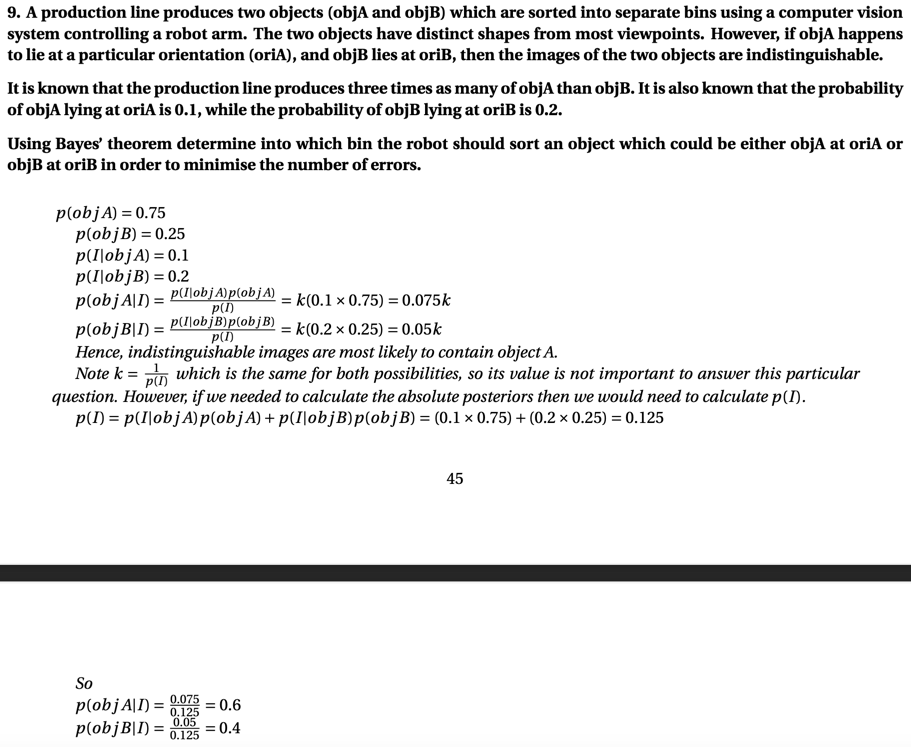

% A production line produces two objects (objA and objB) which are sorted into separate bins using a computer vision system controlling a robot arm. The two objects have distinct shapes from most viewpoints. However, if objA happens to lie at a particular orientation (oriA), and objB lies at oriB, then the images of the two objects are indistinguishable. It is known that the production line produces three times as many of objA than objB. It is also known that the probability of objA lying at oriA is 0.1, while the probability of objB lying at oriB is 0.2. Using Bayes  theorem determine into which bin the robot should sort an object which could be either objA at oriA or objB at oriB in order to minimise the number of errors.
% P_A + P_B = 1
P_A = 0.75;
P_B = 0.25;
P_I_given_A = 0.1;
P_I_given_B = 0.2;
P_I = P_I_given_A * P_A + P_I_given_B * P_B;

P_A_given_I = P_I_given_A * P_A / P_I

P_A_given_I = 0.6000

P_B_given_I = P_I_given_B * P_B / P_I

P_B_given_I = 0.4000

function out = location_in_img(x,y,principal_point,p)
    matrix = [x 0 principal_point(1) 0
              0 y principal_point(2) 0
              0 0 1 0];
    p_T = p.';
    p_T(4) = 1;
    out = 1/p(3) * matrix * p_T;
end

function out = sum_matrix(x)
    out = sum(sum(x));
end

function out = background_subtraction(I, B, beta)
    out = (1-beta)*B + beta*(I);
%     out = abs(I - t_B);
end

function out = cal_lines(pixel, thetas)
    array = zeros(1,length(thetas));

    for i = 1:length(thetas)
        array(i) = round(pixel(2)*cosd(thetas(i)) - pixel(1)*sind(thetas(i)), 0);
    end
    out = array;
end

function out = gaussian2D(x, y, std)
    out = (1 / (2 * pi * std^2)) * exp(- (x^2 + y^2) / (2 * std^2));
end

function out = find_depth(f,z)
    out = 1 / (1/f - 1/z);
end